# RBE500: Foundations of Robotics 

# Week 10 : Joint Control

**Kathia Coronado**

*Robotics Engineering Graduate Student, Worcester Polytechnic Institute, Worcester, Massachussets, kcoronado@wpi.edu*

# Introduction 

THe purpose of this weeks assignment was to practive and learn sampling methods in order to to obtain an optimal mobile plan path. In this assignment, we were tasked with creating our own binary occupancy space. Using this space, the RRT sampling method of obtaining an optimal path was used. The is a very popoular and useful method of sampling and branching out within the workspace for the purpose of discovering the best paths to the desired position.

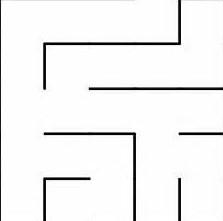

Figure 1 - Image used to create the pathmap

# Methods and Results 

For this assingment, I used two matlab suorse codes, to development my solution. 

First I used MATLABS binaryoccupancymap function to turn an rgb image of a maze into a binary image or mask  that I can use to differentiate the free space and occpied space in my submission.

In order to accomplish this I needed to : 

Create a state space.

clc; clear;
ss = stateSpaceSE2;

Create an `occupanyMap`-based state validator using the created state space.

sv = validatorOccupancyMap(ss);

Create an occupany map from an image

%load exampleMaps

image = imread('C:\Users\thomm\Documents\KATHIA\ez_ez.png');

Convert to grayscale and then black and white image based on given threshold value.

grayimage = rgb2gray(image);
bwimage = grayimage <150;

Use black and white image as matrix input for binary occupancy grid.

gridy = binaryOccupancyMap(bwimage);


map = gridy;
sv.Map = map;

Set validation distance for the validator.

sv.ValidationDistance = 0.05;

Update state space bounds to be the same as map limits.

ss.StateBounds = [map.XWorldLimits;map.YWorldLimits; [-pi pi]];

Create the path planner and increase max connection distance.

planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 0.5;

Set the start and goal states.

start = [50,200, 0];
goal = [200,50,0];

Plan a path with default settings.

rng(100,'twister'); % for repeatable result
[pthObj,solnInfo] = plan(planner,start,goal);


Visualize the results.

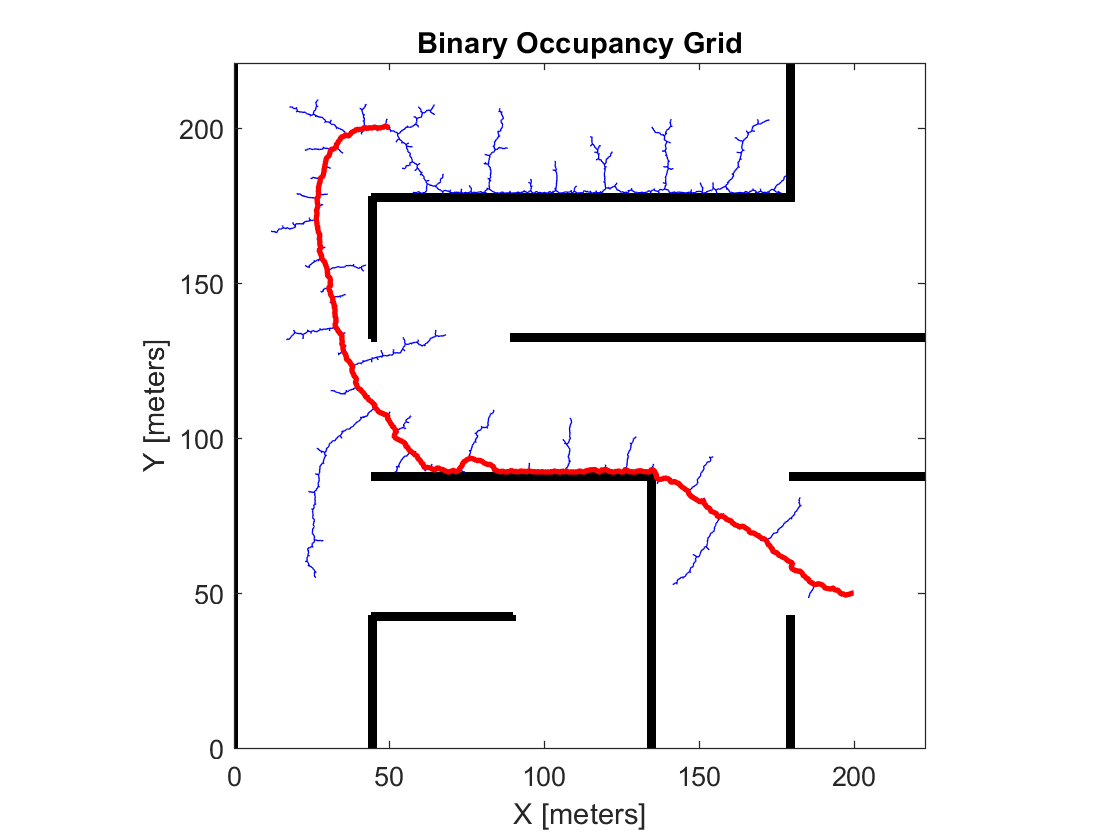

show(map)
hold on
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'b-'); % tree expansion
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2) % draw path
hold off

Now graphing of deltax , delta y and delta theta. 

To do this I took the navpath object produced by the plan function and plotted  the differential of its 3 outputs and against the step size.  

This plot displays the change in direction per step size, which is the velocity of the system. Delta x and Delta y are linear velocities and Delta theta is the angular velcity.


pathobj=pthObj % navpath object

pathobj =   navPath with properties:

    StateSpace: [1×1 stateSpaceSE2]
        States: [647×3 double]
     NumStates: 647


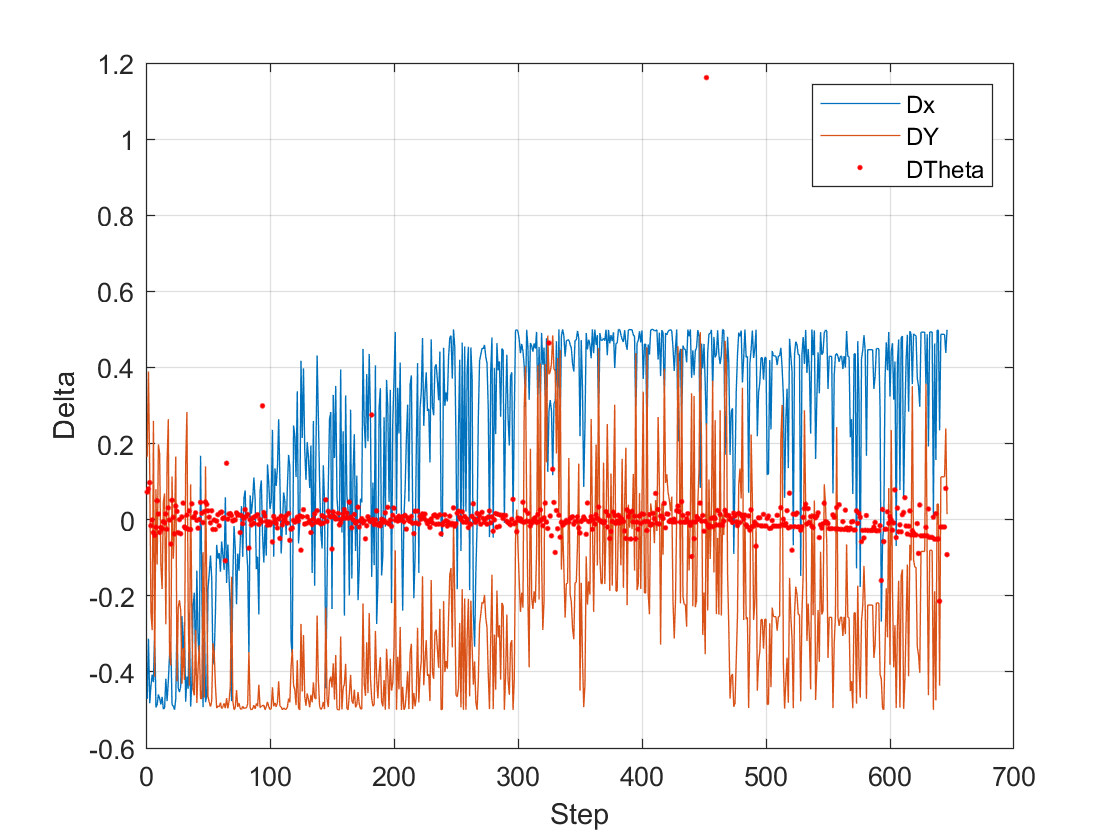



figure
% delta x 
%plot3(diff(pathobj.States(:,1)), diff(pathobj.States(:,2)), diff(pathobj.States(:,3)) );
plot(diff(pathobj.States(:,1)));
hold on
plot( diff(pathobj.States(:,2)));
hold on
plot(diff(pathobj.States(:,3)), '.r');
%hold on
%plot(diff(waypoints(:,1)),diff( waypoints(:,2)), ".r", "MarkerSize", 20);
grid on;

hold off
legend('Dx','DY','DTheta')
ylabel('Delta')
xlabel('Step')

*Copyright 2019 The MathWorks, Inc.*

# Discussion

This assignment involved using RRT, a sampling trial and error computational methods in order to obtain the most optimatl path between the desired start and end position. While doing this assignmnet is was very interesting to manipulate the different parameters involved with RRT and then visualizing these changes by analyzing the resulting " optimal" path. While doing the first porition of this assingment I found that having a small validation and small connection distance produces the most straightforward and shortest path. Also while playing around with different work spaces, I found that smaller workspaces tend to have a better result. 

The second portion of this assingment involved analyzing the differentials of the x and y position and the differential of theta of the system. I order to do this, I plotted these differentials on the same plot in order to better compare them.  In the plot the differentials are plotted against a step, therefore the plot is showing velocity of x, y and theta.  looking at the plot it looks like the angle theta did not change much it was relatively stable, this was to be expected as the path produced by the algorthm did not involve a great a mount of turn or angles. The x and y position differentital differ about the same. 

All in all this was an interesting and short assignment. I really enjoyed learning ang getting practive with the RRT method. It was interesting and very rewarding to see the parameters that affect the legnth of the of the optimal path.

## References

(1) Spong et al. (2020).* Robot Modeling and Control *(2nd Edition). Wiley.